# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');

## Costanti del motore

Definizione delle costanti necessarie alla modellizzazione del comportamento del motore.

k_t = 0.1; % Costante di coppia [Nm/A]
R = 0.13; % Resistenza interna del motore[ohm]
L = 0.10e-3; % Induttanza del motore [H]
tau_e = L/R; % Costante di tempo elettrica [m]
tau = 0.1*22/26; % Rapporto di trasmissione
J_m_star = 3.7e-4+double(J_r)*tau^2; %Inerzia del motore ridotta all'albero [kg m^2]
fc=1000;
wc=2*pi*fc;
ti_i = tau_e;
kg_i = wc*tau_e*R; 
PI_I = kg_i*tf([ti_i,1],[ti_i,0])


PI_I =
 
  0.0004833 s + 0.6283
  --------------------
      0.0007692 s
 
Continuous-time transfer function.



## Modellizzazione del motore

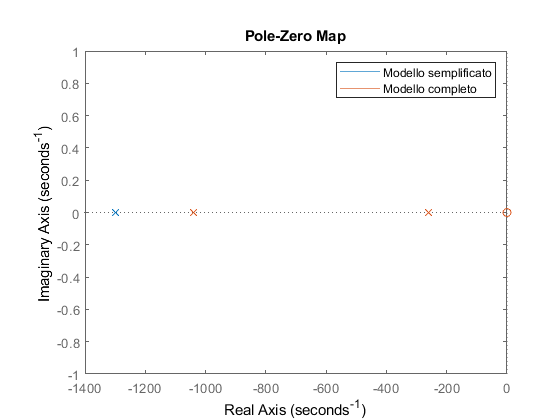

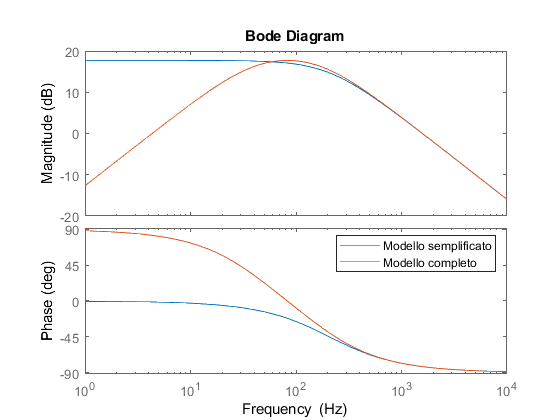

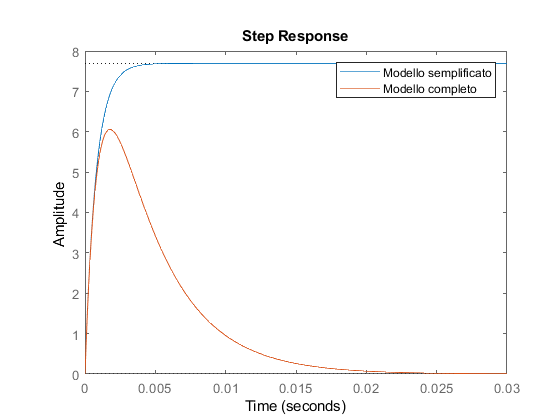

motor = struct with fields:
             name: 'Sinobi Serie 75 PX 053'
               Vn: 2050
               Wn: 870
               Cn: 3.6000
               In: 37
             Imax: 20
               Ra: 0.1300
               La: 1.0000e-04
                K: 0.1000
              tee: 0.0012
               Jm: 3.7000e-04
         J_m_star: 0.0014
                m: 8.1000
       radialLoad: 380
        axialLoad: 110
               te: 7.6923e-04
               tm: 0.0048
    tf_V_I_simple: [1×1 tf]
           tf_V_I: [1×1 tf]
           tf_V_w: [1×1 tf]


J_rotore = double(J_r) * tau^2;
motor = ConfigDCMotor(1, J_rotore)

K_gi = 0.6283


PI_I =
 
  0.0004833 s + 0.6283
  --------------------
      0.0007692 s
 
Continuous-time transfer function.



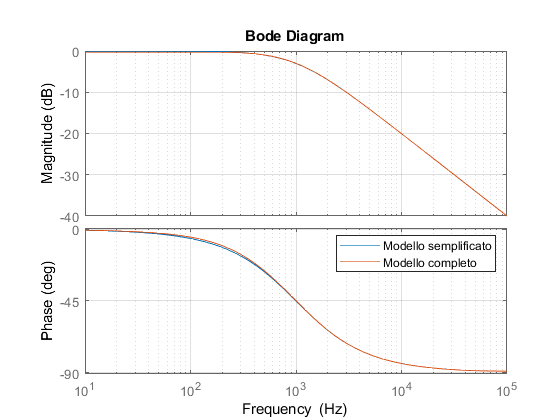

currentClosedLoop = struct with fields:
             f_c: 1000
             w_c: 6.2832e+03
             Kgi: 0.6283
    PI_regulator: [1×1 tf]
             H_I: [1×1 tf]
      H_I_simple: [1×1 tf]


currentClosedLoop = CurrentLoop(motor)

motor_selection = 0;

## Analisi stabilità e discretizzazione

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

Ts = 0.01;

sys = ss(A_real,B_real,C_real,D_real) % Same of G


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -15.23       0
   x3       0       0       0       1
   x4       0       0   5.439       0
 
  B = 
            u1
   x1        0
   x2     2.75
   x3        0
   x4  -0.2612
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



sys_d = c2d(sys,Ts, 'tustin')


sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1        0.01  -0.0007615  -3.808e-06
   x2           0           1     -0.1523  -0.0007615
   x3           0           0           1        0.01
   x4           0           0      0.0544           1
 
  B = 
               u1
   x1   0.0001375
   x2      0.0275
   x3  -1.306e-05
   x4   -0.002612
 
  C = 
               x1          x2          x3          x4
   y1           1       0.005  -0.0003808  -1.904e-06
   y2           0           1    -0.07615  -0.0003808
   y3           0           0           1    0.005001
   y4           0           0      0.0272           1
 
  D = 
               u1
   y1   6.875e-05
   y2     0.01375
   y3  -6.531e-06
   y4   -0.001306
 
Sample time: 0.01 seconds
Discrete-time state-space model.



A_d = sys_d.a;
B_d = sys_d.b;
C_d = sys_d.c;
D_d = sys_d.d;

## Analisi grafiche

eig(A_d)

ans =     1.0000
    1.0000
    1.0236
    0.9769


Come si vede il sistema non è asintoticamente per la presenza di autovalori esterni al cerchio unitario.

Questo è confermato anche dalla presenza di poli all'esterno del cerchio unitario.

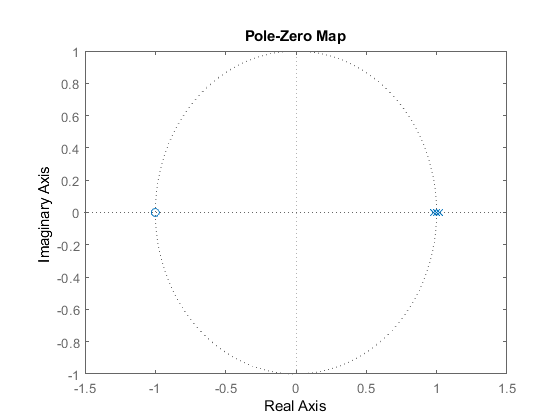

pzmap(sys_d)

M_r = ctrb(sys_d) % Matrice di raggiungibilità

M_r =     0.0001    0.0004    0.0007    0.0010
    0.0275    0.0275    0.0275    0.0275
   -0.0000   -0.0000   -0.0001   -0.0001
   -0.0026   -0.0026   -0.0026   -0.0026


rank(M_r)

ans = 4

M_o = obsv(sys_d) % Matrice di osservabilità

M_o =     1.0000    0.0050   -0.0004   -0.0000
         0    1.0000   -0.0762   -0.0004
         0         0    1.0001    0.0050
         0         0    0.0272    1.0001
    1.0000    0.0150   -0.0019   -0.0000
         0    1.0000   -0.2285   -0.0019
         0         0    1.0007    0.0150
         0         0    0.0816    1.0007
    1.0000    0.0250   -0.0050   -0.0000
         0    1.0000   -0.3810   -0.0050


rank(M_o)

ans = 4

Si vede come il sistema, in anello aperto, non sia asintoticamente stabile (come previsto), dalle analisi sugli autovalori e sui poli.

Lo stato del sistema, nel nostro caso, risulta essere accessibile, poichè sono misurazioni che possono essere direttamente realizzate per mezzo di tecniche di sensor fusion.

## Posizionamento dei poli discreti

syms xsi wn1 wn2 s;
% Definisco le funzioni di trasferimento
dd_1 = s^2 + s * 2 * xsi * wn1 + wn1^2 == 0

$$dd\_1 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{1}+{{\mathrm{wn}}_{1}}^{2}=0$$

dd_2 = s^2 + s * 2 * xsi * wn2 + wn2^2 == 0

$$dd\_2 = s^{2}+2\,\mathrm{xsi}\,s\,{\mathrm{wn}}_{2}+{{\mathrm{wn}}_{2}}^{2}=0$$

sol_dd_1 = solve(dd_1, s);
sol_dd_2 = solve(dd_2, s);

Definisco la pulsazione naturale per primo polo, destinato al controllo più veloce per l'angolo $\theta \;\ldotp$

% fn1 = 20; % [Hz]
fn1 = 0.2; % [Hz]
w1 = 2*pi*fn1; % [rad / s]

Definisco i parametri anche per il secondo polo, invece più lento e destinato a $\phi \;\ldotp$

% fn2 = 2; % [Hz]
fn2 = 0.02; % [Hz]
w2 = 2*pi*fn2; % [rad / s]

Definisco anche lo smorzamento per i poli

e =0.7; % Smorzamento

Sostituisco i parametri numeri di pulsazione e smorzamento nelle soluzione dei poli:

pol_1 = subs(sol_dd_1,{xsi,wn1},{e,w1});
pol_2 = subs(sol_dd_2,{xsi,wn2},{e,w2});
pol_1_real = double(pol_1)

pol_1_real =   -0.8796 + 0.8974i
  -0.8796 - 0.8974i


pol_2_real = double(pol_2)

pol_2_real =   -0.0880 + 0.0897i
  -0.0880 - 0.0897i


K_d = place(A_real,B_real,[pol_1_real', pol_2_real'])

K_d =    -0.0023   -0.0278  -28.1397   -7.7022


Calcolo la nuova matrice A in anello chiuso con i valori di K:

A_cl = A_d - B_d * K_d;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl)

ans =    0.9991 + 0.0009i
   0.9991 - 0.0009i
   0.9913 + 0.0091i
   0.9913 - 0.0091i


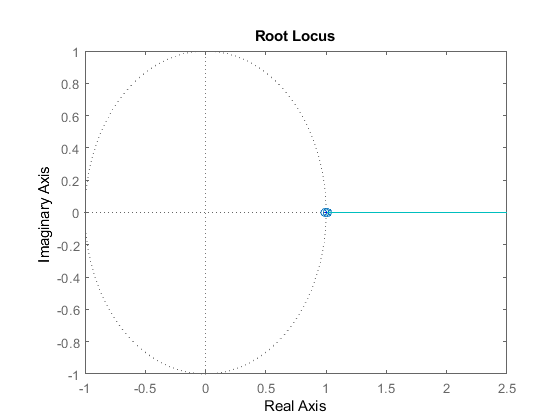

sys_cl = c2d(ss(A_cl,B_d,[0,0,1,0],[0]), Ts);
rlocus(sys_cl)

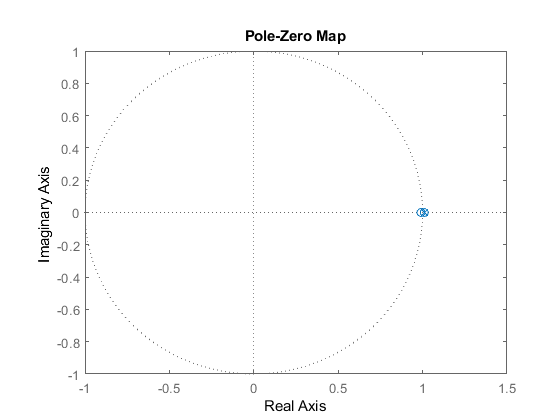

pzmap(sys_cl)

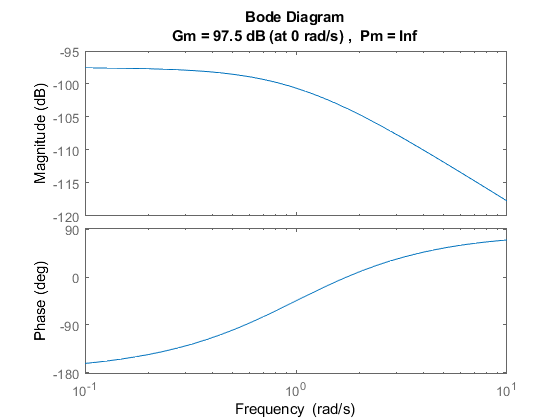

margin(sys_cl)

Si vede quindi come, soprattutto dal luogo delle radici, che abbiamo ottenuto la possibilità di andare a muovere i poli nel semipiano a parte reale negativa.

Posso utilizzare un'altra tecnica per realizzare il place dei poli (LQR - Regolatore Lineare Quadratico) che rappresenta una soluzione ottima per il pole placement:

Q = eye(4);
R = 1;
K_lqr_d = dlqr(A_d,B_d,Q,R)

K_lqr_d =    -0.9613   -2.2598 -112.2797  -53.3869



k_simulazione_discreta = K_d;

A_cl_lqr_d = A_d - B_d * K_lqr_d;

Verifico che i nuovi autovalori abbiano parte reale negativa.

eig(A_cl_lqr_d)

ans =    0.9672 + 0.0000i
   0.9879 + 0.0025i
   0.9879 - 0.0025i
   0.9788 + 0.0000i


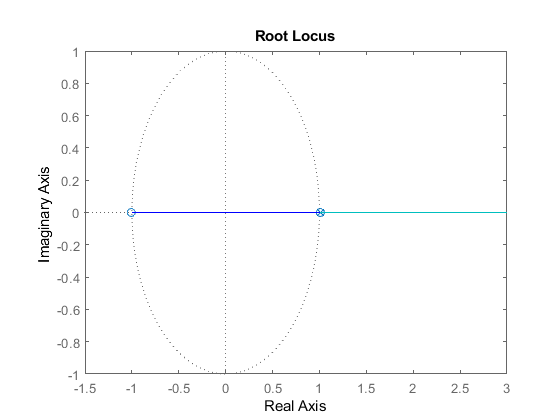

sys_cl_lqr_d = c2d(ss(A_cl_lqr_d,B_real,[0,0,1,0],[0]), Ts);
rlocus(sys_cl_lqr_d)

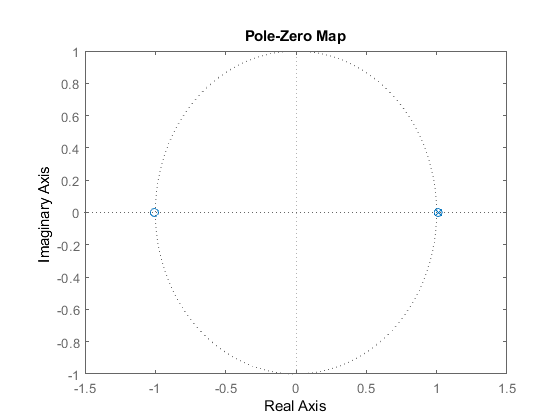

pzmap(sys_cl_lqr_d)

## Simulazione

### Condizioni iniziali

% Initial condition for open loop model
x_0 = [0; 0; 5 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
r_simulazione = double(r);
control_on = 1;
t_end = 10;
Ts = 1/100;
control_on = 1;
%vale solo nel non lineare alpha
alpha_simulazione = double(0);

## Simulazione discreta

### Sistema lineare

disp('Closed loop');

Closed loop


disp('Linear discrete system');

Linear discrete system


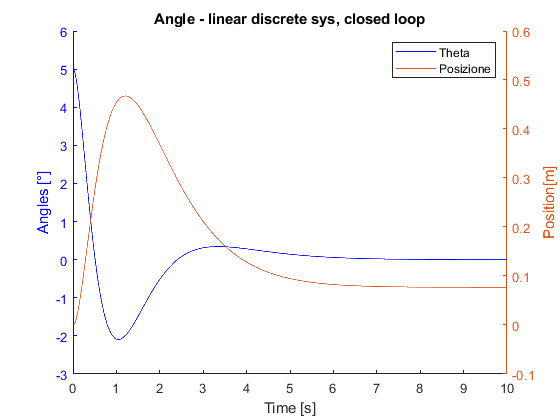




simOut = sim('VAB_Linear_Discrete');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
actual_torque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear discrete sys, closed loop')
hold off

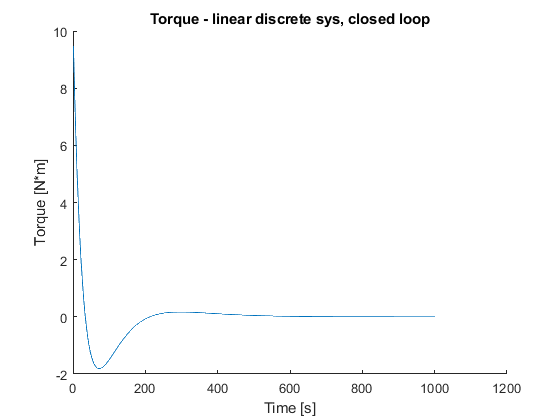

figure
hold on
plot(torque)
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear discrete sys, closed loop')
hold off

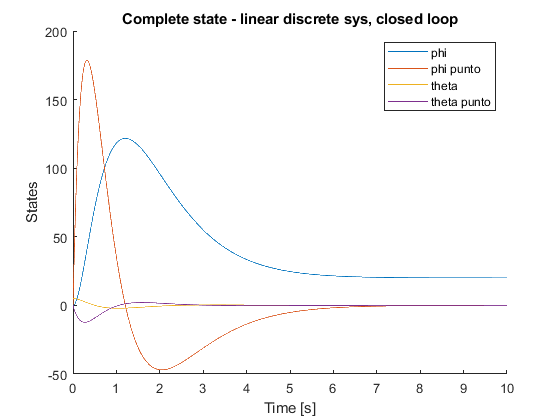


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear discrete sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

## Sistema non lineare

disp('Non linear discrete system');

Non linear discrete system


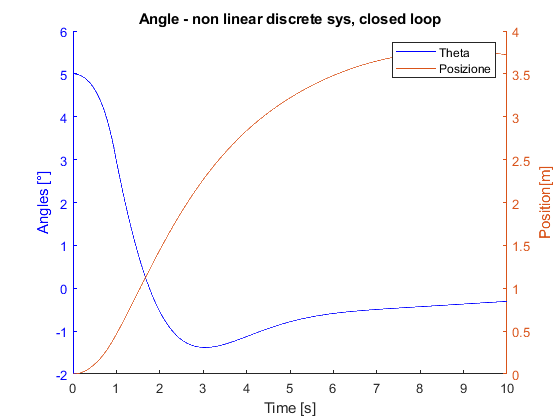

control_on = 1;
simOut = sim('VAB_non_linear_Discrete.slx');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torque = simOut.TorqueFeeded;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;
actual_torque = simOut.actualTorque;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear discrete sys, closed loop')

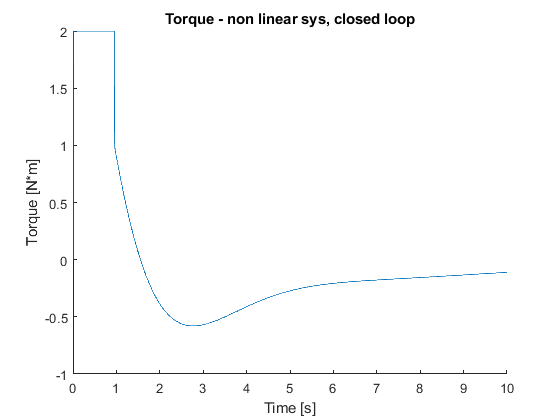

figure
hold on
plot(tout, actual_torque)
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear sys, closed loop')
hold off

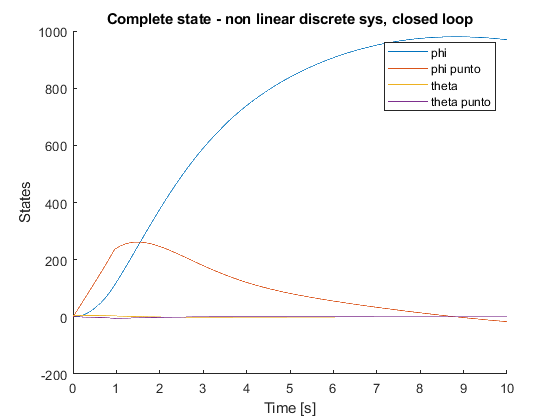


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear discrete sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

clearvars ax

NB: State needs to be defined in rad!

%call_plot(completeState * pi / 180);